sensor_data = load("pitch_out.mat");
pitch_angle = sensor_data.data.Data;
time = sensor_data.data.Time;

fs = 1/0.01;

n = length(pitch_angle); % Number of Samples
f = (0:n-1)*(fs/n); % Frequency range
Y = fft(pitch_angle);
P2 = abs(Y/n);
P1 = P2(1:n/2+1);

P1(2:end-1) = 2*P1(2:end-1);

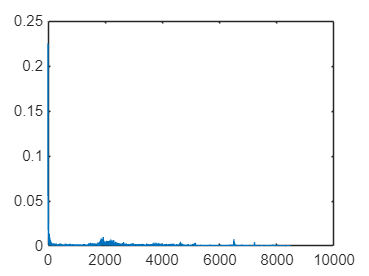

[~, index] = max(P1);
plot(P1)